Import the image

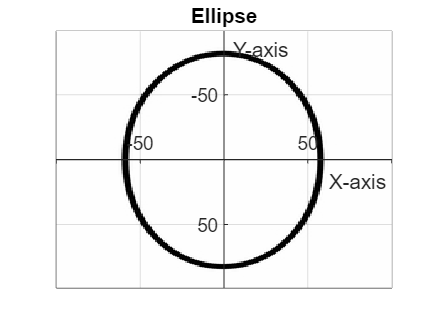

% Load the image
f = imread('ellipse.jpg');
f = double(f);
plot_ellipse(f);

Compute the 2-dimensional Gaussian function values

sigma = 1; % standard deviation for Gaussian

G = gaussian_function(sigma);

Compute the 2d-convolution

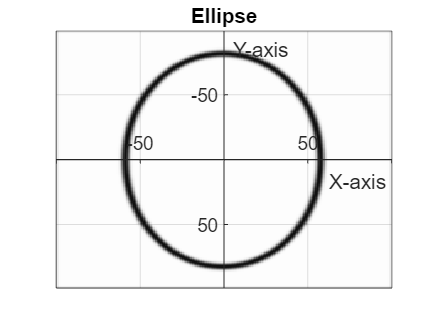

f_smooth = conv2(f, G, 'same');
plot_ellipse(f_smooth);

An edge is defined when

[df_smooth_x, df_smooth_y] = gradient(f_smooth);
gradient_norm = sqrt(df_smooth_x.^2 + df_smooth_y.^2);

is large, and when

M = mexican_hat(sigma);
d_f_smooth_2 = conv2(f, M, 'same');

df_smooth_2_abs=abs(second_oder_derivate_f_smooth);

is small.

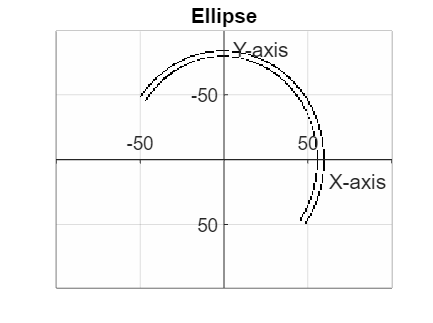

f_feature = canny_edge_detector(gradient_norm, df_smooth_2_abs, 80, 400);
plot_ellipse(f_feature)

function G = gaussian_function(sigma)
    % Define the kernel size
    size = 2 * ceil(3 * sigma) + 1;
    
    % Create the coordinate grid
    x = -(size - 1) / 2 : (size - 1) / 2;
    
    % Define the 1D Gaussian function
    g = (1 / (sigma * sqrt(2 * pi))) * exp(-(x .^ 2) / (2 * sigma ^ 2));
    
    % Compute the 2D Gaussian kernel using outer product
    G = g' * g;
end

function f_feature = canny_edge_detector(gradient_norm, df_2_smooth_abs, d1, d2)
    [n, m] = size(gradient_norm);
    f_feature = 255*ones(n, m);  % Or preallocate a numeric matrix if possible

    % Loop through each unique pair
    for i = 1:n
        for j = i:m
            if gradient_norm(i,j) > d1 && df_2_smooth_abs(i,j) < d2
            % Put the pair (i,j) in the feature set
            f_feature(i, j) = 0;
            end
        end
    end
end

function M = mexican_hat(sigma)
    % Define the kernel size
    size = 2 * ceil(3 * sigma) + 1;
    
    % Create the coordinate grid
    [x, y] = meshgrid(-(size - 1) / 2 : (size - 1) / 2);

    % Define the Mexican Hat function
    M = (x.^2 + y.^2 - 2 * sigma^2) ./ (sigma^4) .* exp(-(x.^2 + y.^2) / (2 * sigma^2));
end

function plot_ellipse(img)
    %Get image dimensions
    [imageHeight, imageWidth, ~] = size(img);
    
    % Display the image
    figure;
    image(img, 'XData', [-imageWidth/2, imageWidth/2], 'YData', [-imageHeight/2, imageHeight/2]);
    colormap gray;
    %hold on;
    
    % Set up the axes
    ax = gca;
    ax.XAxisLocation = 'origin';
    ax.YAxisLocation = 'origin';
    
    % Define the axis limits to match the image dimensions
    xlim([-imageWidth/2, imageWidth/2]);
    ylim([-imageHeight/2, imageHeight/2]);
    
    % Enable grid
    grid on;
    
    % Label axes
    xlabel('X-axis');
    ylabel('Y-axis');
    title('Ellipse');
end